# Car parking case study

#### Case study: Two dimensional model

Author: Birgit van Huijgevoort

In this case study, the objective is to design a controller such that the car model eventually reaches the parking area whilst avoiding an prespecified unsafe area.

#### Initialization

clc; clear; close all;

% Add toolboxes to path
run Install.m

Please add either tensortoolbox or tensor lab to your path
 You can download the tensortoolbox for matlab from  https://www.tensortoolbox.org
MPT toolbox is not automatically installed
Yalmip and Mosek are not automatically installed


% Track runtime
tStart = tic;

## Specify system parameters and regions

LTI systems of the form: 

x(t+1) = Ax(t) + Bu(t) + Bw w(t) 

y(t) = Cx(t) + Du(t)

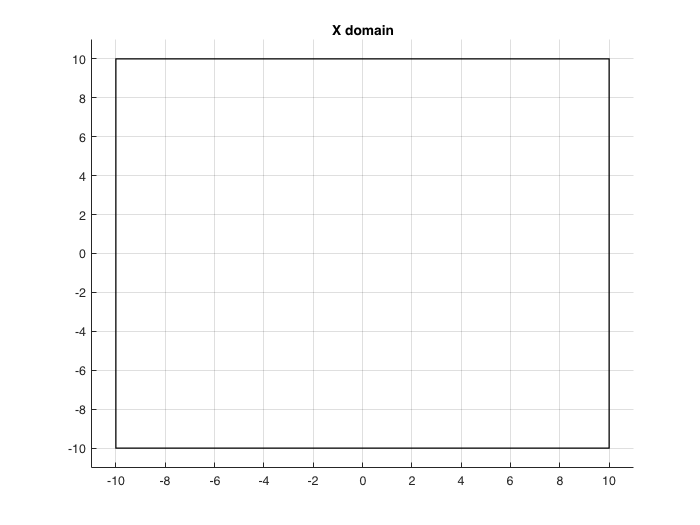

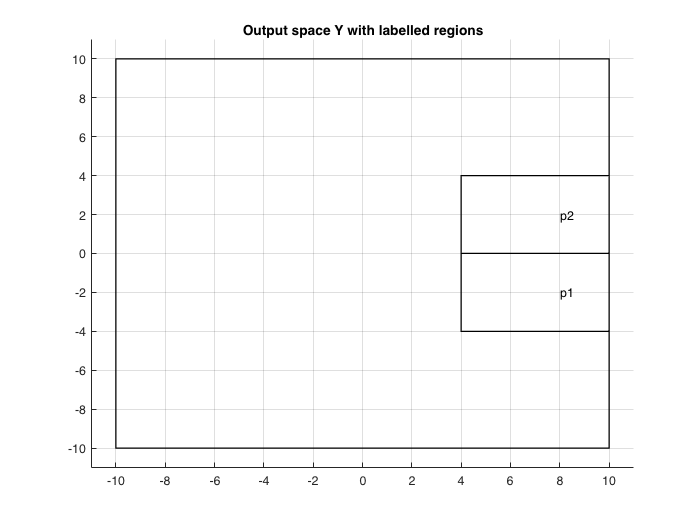

% Define system parameters
A = 0.9*eye(2);
B = 0.7*eye(2);
C = eye(2);
D = zeros(2);
Bw = eye(2);
dim = length(A);

% Specify mean and variance of disturbance w(t) 
mu = zeros(dim,1); % mean of disturbance
sigma = eye(dim); % variance of disturbance

sysLTI = LinModel(A,B,C,D,Bw,mu,sigma);
 
% Bounds on state space 
x1l = -10;   % Lowerbound x1
x1u = 10;   % Upperbound x1
x2l = -10;   % Lowerbound x2
x2u = 10;   % Upperbound x2
sysLTI.X = Polyhedron(combvec([x1l,x1u],[x2l,x2u])');

% Bounds on  and input space
ul = [-1;-1];   % Lowerbound input u
uu = [1;1];     % Upperbound input u
sysLTI.U = Polyhedron(combvec([ul(1),uu(1)],[ul(2),uu(2)])');

% Specify regions for the specification
% 1) Parking region
p1x = [4 4 10 10 4];    % x1-coordinates
p1y = [0 -4 -4 0 0];    % x2-coordinates
p1 = [p1x; p1y];         % parking region
P1 = Polyhedron(p1');

% 2) Avoid region
p2x = [4 4 10 10 4];    % x1-coordinates
p2y = [0 4 4 0 0];      % x2-coordinates
p2 = [p2x; p2y];        % avoid region
P2 = Polyhedron(p2');

sysLTI.regions = [P1;P2]; % regions that get specific atomic propositions
sysLTI.AP = {'p1', 'p2'}; % with the corresponding atomic propositions

Plot_sysLTI(sysLTI)

## Synthesize scLTL formula (or input DFA yourself)

### Use LTL2BA and check if determinstic and accepting state is sink state

input: (sc)LTL formula and atomic propositions (see readme in folder LTL2BA) 

output: struct DFA containing (among other) the transitions

formula = '(!p2 U p1)';  % p1 = parking, p2 = avoid region
% formula should use atomic propositions in sysLTI.AP

% Generate DFA
% (Make sure your current folder is the main SySCoRe folder)
[DFA] = TranslateSpec(formula,sysLTI.AP);

never { /* (!p2 U p1) */
T0_init:
	if
	:: (!p2) -> goto T0_init
	:: (p1) -> goto accept_all
	fi;
accept_all:
	skip
}

add state


## Construct abstract model by gridding it

disp('Start gridding...');

Start gridding...


tGridStart = tic;
% input: sysLTI, sigma, space bounds for input (controller) and state space

% Specify division of input space for actuation and feedback
ula = 1*ul;   % part of input for actuation (lowerbound)
uua = 1*uu;
ulf = ul-ula;   % part of input for feedback (lowerbound)
uuf = uu-uua;

% Specify granularity of abstraction/gridding
lu = 6; % Division of input space
lx1 = 200; % Division of state space in x1-direction
lx2 = 200; % Division of state space in x2-direction
 

uhat = combvec(linspace(ula(1),uua(1),lu),linspace(ula(2),uua(2),lu));

l = [lx1, lx2];  % number of grid cells in x1- and x2-direction
tol = 10^-6;
sysAbs = Gridding(sysLTI,uhat,l,tol,'TensorComputation',true);

% Save some extra system parameters into struct
sysAbs.orig = sysLTI;

% Label state space
label = zeros(1,prod(l));
[label(1:prod(l))] = deal(1);
inP1 = inpolygon(sysAbs.states(1,:),sysAbs.states(2,:),p1x,p1y);
inP2 = inpolygon(sysAbs.states(1,:),sysAbs.states(2,:),p2x,p2y);
[label(inP1)] = deal(3);
[label(inP2)] = deal(2);
sysAbs.labels = label;

tGridEnd = toc(tGridStart);
disp(['---> finished gridding in ', num2str(tGridEnd), ' seconds'])

---> finished gridding in 0.31456 seconds


## Compute delta based on epsilon

disp('Start computing eps delta...');

Start computing eps delta...


tSimStart = tic;

% Pick epsilon
epsilon = 0.15;
 

% Calculate delta based on chosen epsilon
[delta, D_m, K] = ComputeDelta(epsilon,sysLTI,sysLTI.mu,sysLTI.sigma,sysAbs.beta);

% Calculate simulation relation
rel = SimRel(epsilon,delta,D_m);

tSimEnd = toc(tSimStart);

disp(['delta = ', num2str(delta), ', epsilon = ', num2str(epsilon) ])

delta = 0.050409, epsilon = 0.15


disp(['---> finished computing eps delta in ', num2str(tSimEnd), ' seconds'] )

---> finished computing eps delta in 3.5137 seconds


## Synthesize controller

disp('Start computing robust controller...')

Start computing robust controller...


rel.NonDetLabels  = NonDeterministicLabelling(sysAbs.outputs, sysLTI.regions, rel);

N = 60;     % time horizon

[satProp,pol] = SynthesizeRobustController(sysAbs,DFA, rel, N, true);

 <---- Start computing robust policy 
Elapsed time is 0.001840 seconds.
Elapsed time is 0.418630 seconds.
 ----> Finished computing robust policy in 0.48033


tEnd = toc(tStart);
disp(['Total runtime = ', mat2str(tEnd), ' seconds'])

Total runtime = 6.081567959 seconds


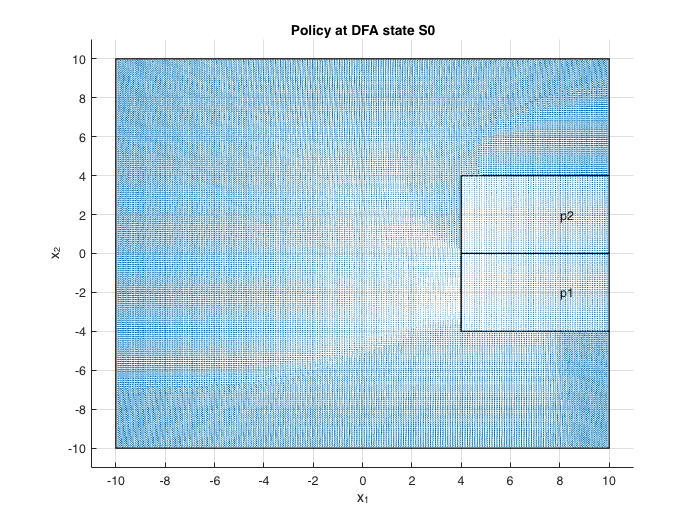

% Check resulting policy
VisualizePolicy(sysAbs, pol, DFA,l, sysLTI)

## Start simulation

x0 = [-4;-5];
xsim = x0;
indexing = 1:length(sysAbs.states);

% Find initial abstract state
diff = abs(x0.*ones(size(sysAbs.states))-sysAbs.states);
inR = (([1 1]*((D_m^.5*diff).^2)).^.5)<=epsilon;
indices_valid = indexing(inR);
[value_max, index_aux] = max(satProp(inR)); 
j = indices_valid(index_aux); % find maximizing index of abstract state    
xhat0 = sysAbs.states(:,j);
xhatsim = [xhat0];
uhat = pol(:,j);

disp([' Satisfaction probability at xhat0 = ', num2str(satProp(j))])

 Satisfaction probability at xhat0 = 0.31407


N = 40;

u = uhat+K*(x0-xhat0);
for i = 1:N
    w1 = sysLTI.mu(1) + sqrt(sysLTI.sigma(1,1)).*randn(1);
    w2 = sysLTI.mu(2) + sqrt(sysLTI.sigma(2,2)).*randn(1);
    w = [w1;w2];
    % Compute next state
    xnext = sysLTI.A*xsim(:,i)+sysLTI.B*u+sysLTI.Bw*w;
    xsim = [xsim, xnext];

    % Stop if you have reached the parking region
    if inpolygon(xnext(1),xnext(2),p1x,p1y)
        disp(['Reached parking area ','after ', num2str(i), ' time instances.']);
        break;
   
    end

    % Find next abstract state by looking at the maximizer in R wrt the value
    % function
    inR = rel.inR(xsim(:,end),sysAbs.states);
    indices_valid = indexing(inR);
    [value_max, index_aux] = max(satProp(inR)); 
    j = indices_valid(index_aux); % find maximizing index of abstract state
    xhatnext = sysAbs.states(:,j);

    % Compute next input
    uhat = [pol(:,j)];
    u = uhat+K*(xnext-xhatnext);
    
    if i==N
        disp(['Did not reach parking after ', num2str(N), ' time instances.'])
    end
end

Reached parking area after 13 time instances.


## Show results

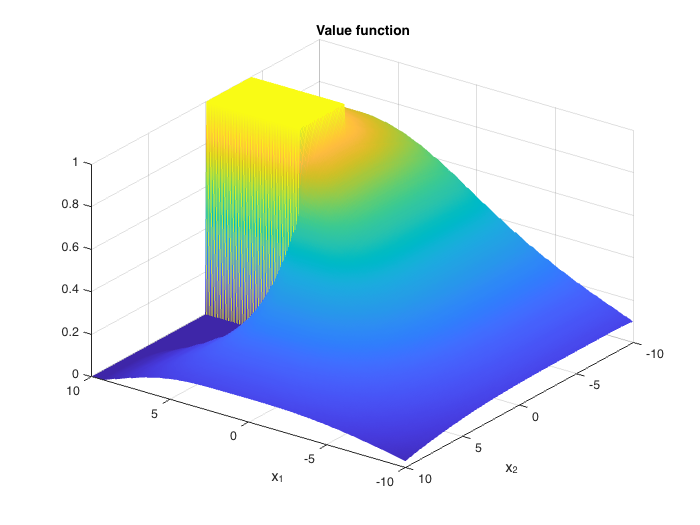

[X1hat, X2hat] = ndgrid(sysAbs.hx{1},sysAbs.hx{2});

figure
surf(X1hat, X2hat,reshape(satProp,l(1),l(2)),'EdgeColor','interp')
xlabel('x_1')
ylabel('x_2')
title('Value function')
view([-144, 36])

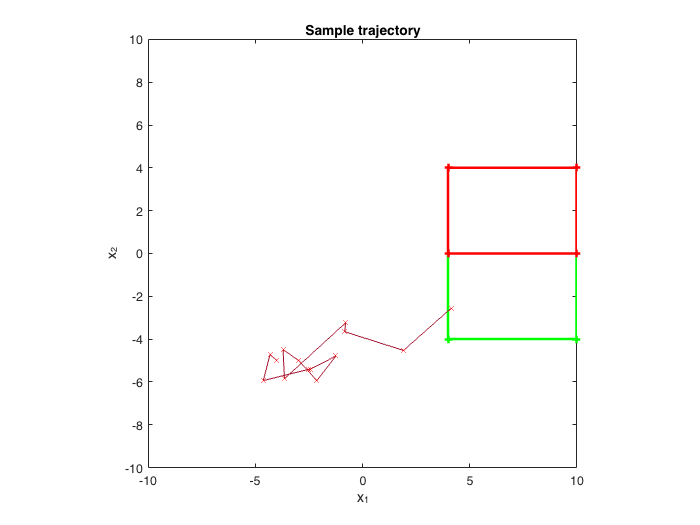

figure(10);
plot(p1x,p1y,'g+-','LineWidth',2)
axis equal
hold on
plot(p2x,p2y,'r+-','LineWidth',2)
xlim([x1l x1u])
ylim([x2l x2u])
xlabel('x_1')
ylabel('x_2')
plot(xsim(1,:),xsim(2,:))
plot(xsim(1,:),xsim(2,:),'rx')
title("Sample trajectory")